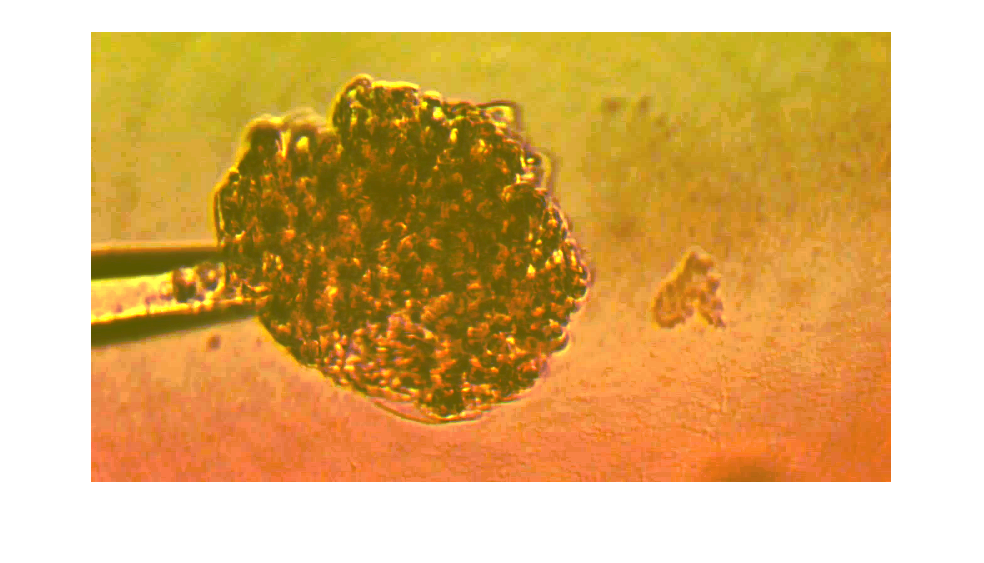

%my own net
%mid_size 
%3 classes
%balance: yes
%shortcut: yes
%shortcut num: 2
%add batch after relu

%the only difference between this model and segTest12 is the batch size is 8
%this is much much better than batch size be 4 
%compared with 15, this has a bigger training data
%compared with 20, this first conv is 7
imageFiles = fullfile('origs');
imageDbs = imageDatastore(imageFiles);

I = readimage(imageDbs,1);
I = histeq(I);
imshow(I)


classes = [
    "Glom"
    "Needle"
    "Background"
    ];
labelIDs = camvidPixelLabelIDs();

labelFiles = fullfile('labels');
lableDbs = pixelLabelDatastore(labelFiles,classes,labelIDs);

%This is for test;
C = readimage(lableDbs,1)

C = 450×800 categorical 数组
  1 至 624 列

     Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background 

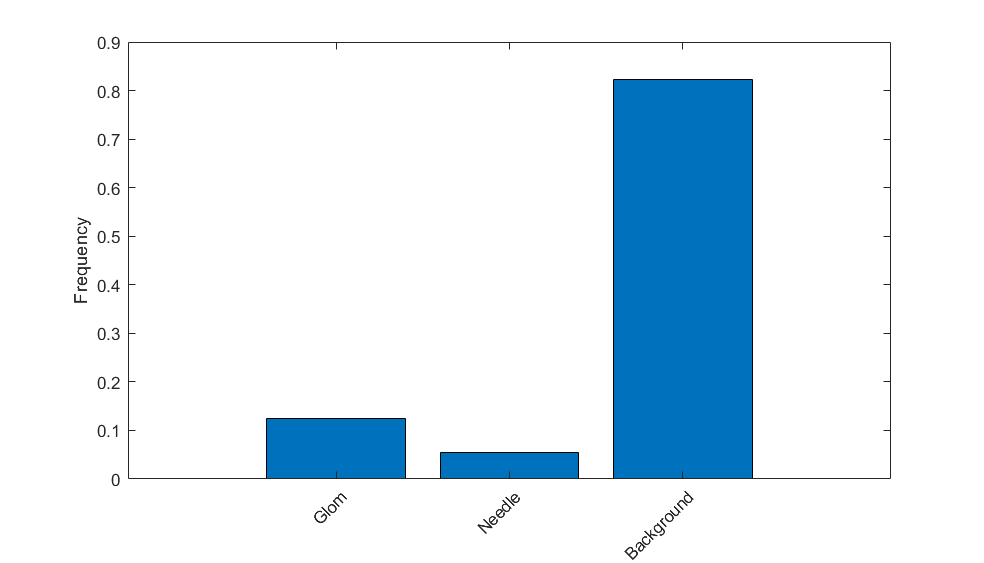

%imshow(C)
%cmap = camvidColorMap;
%B = labeloverlay(I,C,'ColorMap',cmap);
%imshow(B)
%pixelLabelColorbar(cmap,classes);

tbl = countEachLabel(lableDbs);

frequency = tbl.PixelCount/sum(tbl.PixelCount);

bar(1:numel(classes),frequency)
xticks(1:numel(classes))
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')


newsize = [288 512]

newsize =    288   512


resizeOrigs = fullfile('resizeImages_32',filesep);
imageDbs = resizeOrigImages(imageDbs,resizeOrigs, newsize);

resizeLables = fullfile('resizeLables_32',filesep);
lableDbs = resizeLabels(lableDbs,resizeLables, newsize);

[trainImages,testImages,trainLables,testLables] = partitionImages(imageDbs,lableDbs);
  
numTrainingImages = numel(trainImages.Files)

numTrainingImages = 184

numTestingImages = numel(testImages.Files)

numTestingImages = 79


imageSize = [288 512 3];
numClasses = numel(classes);
%use my network

%rebalance the classes
imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq;
lgraph = getMyNet(imageSize, 3, tbl.Name, classWeights);

dowsamplingLayers =   22x1 Layer array with layers:

     1   'con_1'        Convolution           64 7x7 convolutions with stride [1  1] and padding [3  3  3  3]
     2   'relu_1'       ReLU                  ReLU
     3   'batch_con1'   Batch Normalization   Batch normalization
     4   'con_2'        Convolution           64 7x7 convolutions with stride [1  1] and padding [3  3  3  3]
     5   'relu_2'       ReLU                  ReLU
     6   'batch_con2'   Batch Normalization   Batch normalization
     7   'pool_1'       Max Pooling           2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     8   'con_3'        Convolution           128 3x3 convolutions with stride [1  1] and padding [1  1  1  1]
     9   'relu_3'       ReLU                  ReLU
    10   'batch_con3'   Batch Normalization   Batch normalization
    11   'con_4'        Convolution           128 3x3 convolutions with stride [1 

upsamplingLayers_1 =   6x1 Layer array with layers:

     1   'deCon_1'           Transposed Convolution   128 4x4 transposed convolutions with stride [2  2] and output cropping [1  1]
     2   'relu_upSample_1'   ReLU                     ReLU
     3   'batch_upSample1'   Batch Normalization      Batch normalization
     4   'deCon_2'           Transposed Convolution   128 4x4 transposed convolutions with stride [2  2] and output cropping [1  1]
     5   'relu_upSample_2'   ReLU                     ReLU
     6   'batch_upSample2'   Batch Normalization      Batch normalization

upsamplingLayers_2 =   3x1 Layer array with layers:

     1   'deCon_3'           Transposed Convolution   64 4x4 transposed convolutions with stride [2  2] and output cropping [1  1]
     2   'relu_upSample_3'   ReLU                     ReLU
     3   'batch_deCon3'      Batch Normalization      Batch normalization

upsamplingLayers_3 =   3x1 Layer array with layers:

     1   'deCon_4'           Transposed Convolution   64 4x4 transposed convolutions with stride [2  2] and output cropping [1  1]
     2   'relu_upSample_4'   ReLU                     ReLU
     3   'batch_deCon4'      Batch Normalization      Batch normalization

combineLayers_1 =   3x1 Layer array with layers:

     1   'add_1'            Addition              Element-wise addition of 2 inputs
     2   'relu_combine_1'   ReLU                  ReLU
     3   'batch_combine1'   Batch Normalization   Batch normalization

combineLayers_2 =   3x1 Layer array with layers:

     1   'add_2'            Addition              Element-wise addition of 2 inputs
     2   'relu_combine_2'   ReLU                  ReLU
     3   'batch_combine2'   Batch Normalization   Batch normalization

finalLayers =   3x1 Layer array with layers:

     1   'conClass_1'   Convolution                  3 1x1 convolutions with stride [1  1] and padding [0  0  0  0]
     2   'softmax'      Softmax                      softmax
     3   'classify'     Pixel Classification Layer   Cross-entropy loss 

myNet =   44x1 Layer array with layers:

     1   'input'             Image Input                  288x512x3 images with 'zerocenter' normalization
     2   'con_1'             Convolution                  64 7x7 convolutions with stride [1  1] and padding [3  3  3  3]
     3   'relu_1'            ReLU                         ReLU
     4   'batch_con1'        Batch Normalization          Batch normalization
     5   'con_2'             Convolution                  64 7x7 convolutions with stride [1  1] and padding [3  3  3  3]
     6   'relu_2'            ReLU                         ReLU
     7   'batch_con2'        Batch Normalization          Batch normalization
     8   'pool_1'            Max Pooling                  2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     9   'con_3'             Convolution                  128 3x3 convolutions with stride [1  1] and padding [1  1  1  1]
    10  

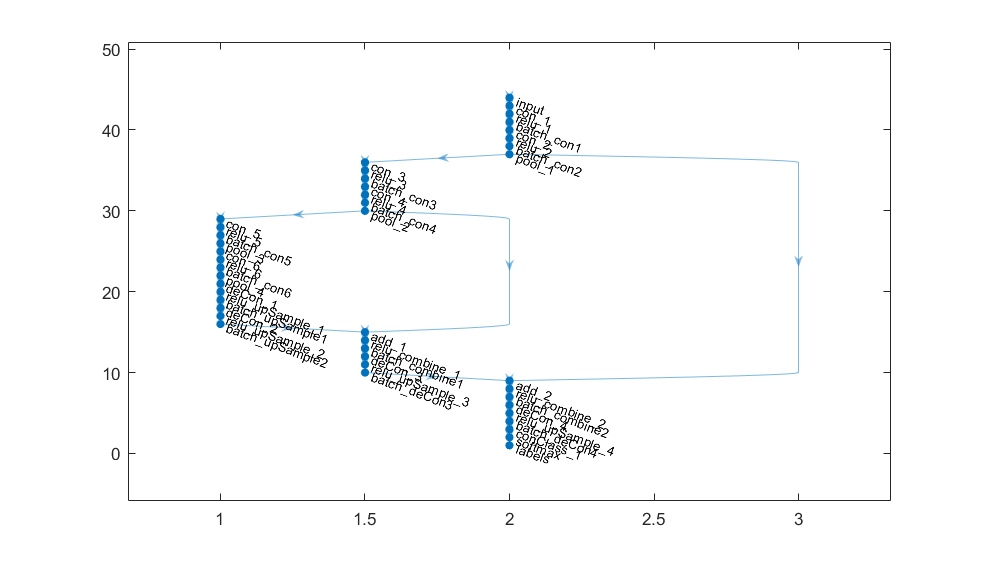

lgraph = layerGraph(lgraph);
lgraph = connectLayers(lgraph, 'pool_2', 'add_1/in2');
lgraph = connectLayers(lgraph, 'pool_1', 'add_2/in2');

pxLayer = pixelClassificationLayer('Name','labels','ClassNames',tbl.Name,'ClassWeights',classWeights);
lgraph = removeLayers(lgraph, 'classify');
lgraph = addLayers(lgraph, pxLayer);
lgraph = connectLayers(lgraph,'softmax','labels');

plot(lgraph)

Initializing image normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:38 |       29.99% |       30.43% |       1.1082 |       1.1091 |          0.0010 |
|       1 |           2 |       00:02:34 |       30.14% |              |       1.1064 |              |          0.0010 |
|       1 |           4 |       00:03:30 |       35.33% |              |       1.0998 |              |          0.0010 |
|       1 |           6 |       00:04:27 |       44.24% |              |       1.0897 |              |          0.0010 

|      56 |        1286 |       13:29:03 |       94.14% |              |       0.0946 |              |          0.0010 |


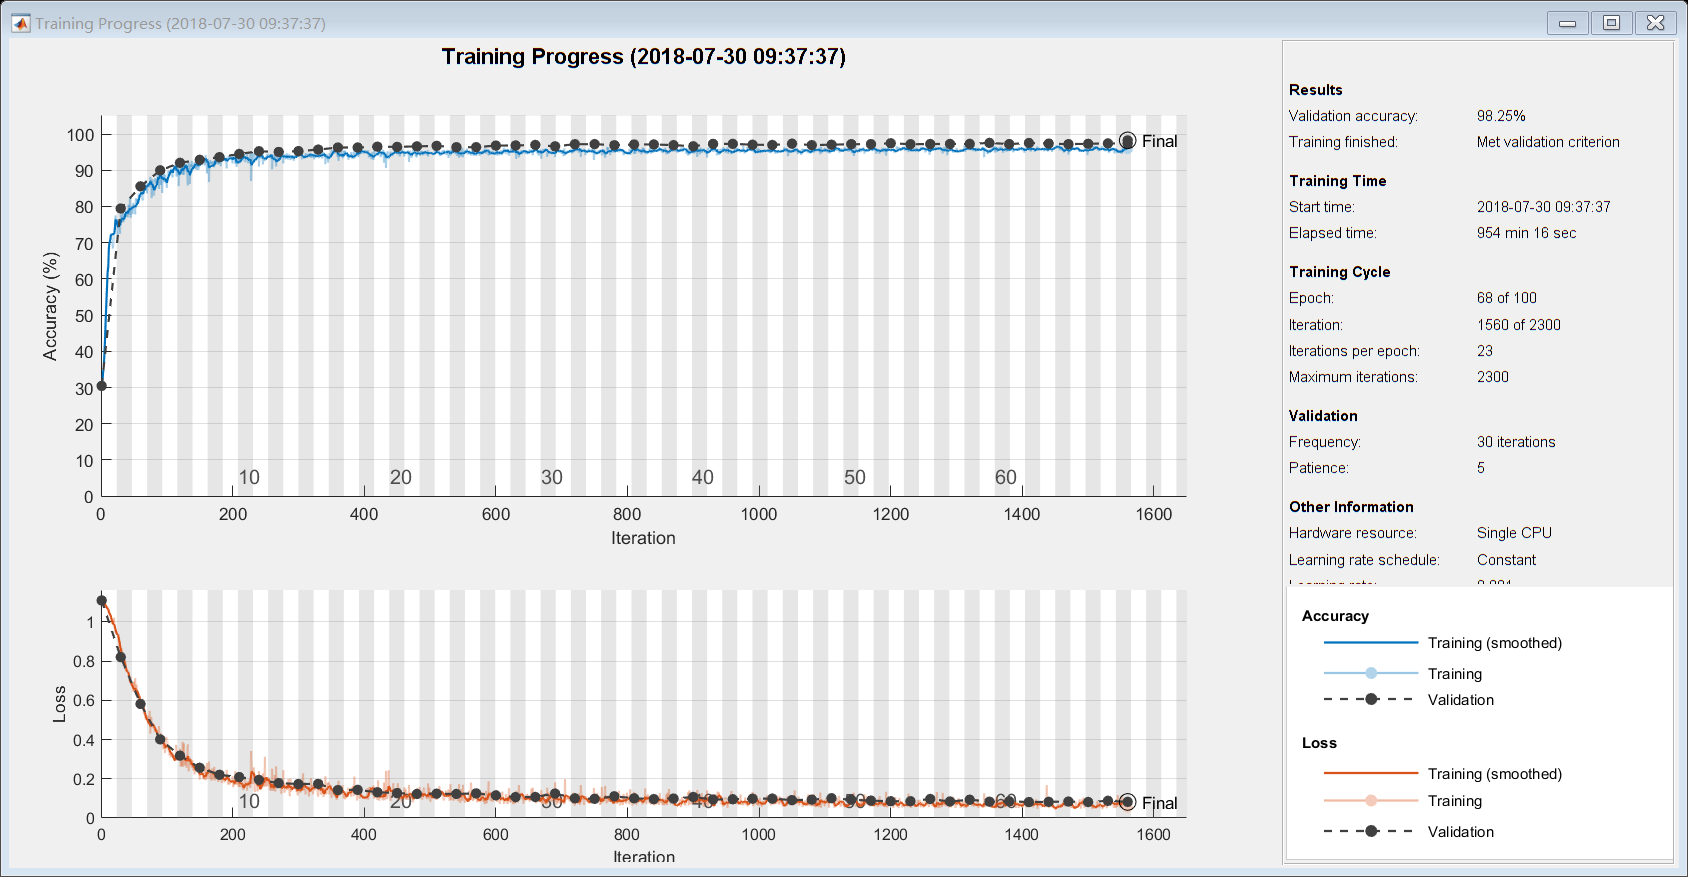

|      56 |        1288 |       13:30:19 |       96.24% |              |       0.0695 |              |          0.0010 |
|      57 |        1290 |       13:31:22 |       95.74% |       97.27% |       0.0634 |       0.0842 |          0.0010 |
|      57 |        1292 |       13:33:56 |       95.88% |              |       0.0546 |              |          0.0010 |
|      57 |        1294 |       13:34:57 |       95.25% |              |       0.1089 |              |          0.0010 |
|      57 |        1296 |       13:35:56 |       95.34% |              |       0.1013 |              |          0.0010 |
|      57 |        1298 |       13:36:54 |       95.59% |              |       0.0511 |              |          0.0010 |
|      57 |        1300 |       13:37:53 |       96.14% |              |       0.0594 |              |          0.0010 |
|      57 |        1302 |       13:38:54 |       95.14% |              |       0.0881 |              |          0.0010 |
|      57 |        1304 |       





%make validation data
validata = pixelLabelImageDatastore(testImages, testLables);

options = trainingOptions('sgdm', ...
    'Plots', 'training-progress', ...
    'Momentum',0.9, ...
    'ValidationData',validata, ...
    'ValidationFrequency', 30, ...
    'InitialLearnRate',1e-3, ...
    'L2Regularization',0.0005, ...
    'MaxEpochs',100, ...
    'MiniBatchSize',8, ...
    'Shuffle','every-epoch', ...
    'ExecutionEnvironment','cpu',...
    'VerboseFrequency',2);

augmenter = imageDataAugmenter('RandXReflection',true,...
    'RandXTranslation',[-10 10],'RandYTranslation',[-10 10]);

pximds = pixelLabelImageDatastore(trainImages ,trainLables,...
    'DataAugmentation',augmenter);

dotrain = true;
if dotrain
    
     [net, info] = trainNetwork(pximds,lgraph,options);
else
    data = load('net.mat');
    net = data.net;
end

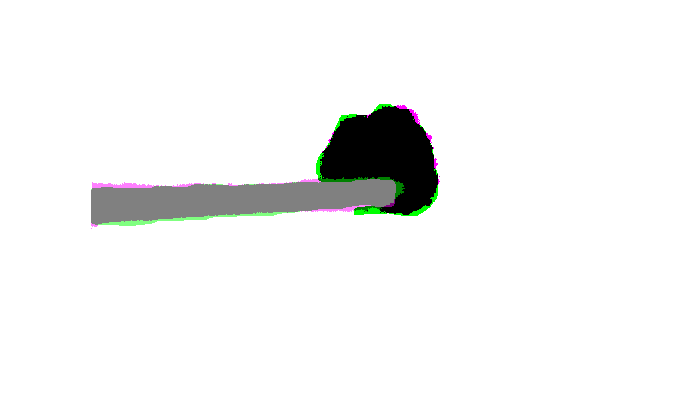


I = read(testImages);

C = semanticseg(I, net);
%I = histeq(I);
%imshow(I)

actual = uint8(C);
expectResult = read(testLables);
expect = uint8(expectResult);
imshowpair(actual, expect)


pxdsResults = semanticseg(testImages,net,'MiniBatchSize',4,'WriteLocation',tempdir,'Verbose',false);

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.


metrics = evaluateSemanticSegmentation(pxdsResults,testLables,'Verbose',false);
metrics.DataSetMetrics

ans = 1×5 table
    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.98261          0.97296       0.9248       0.96651        0.87114  


metrics.ClassMetrics

ans = 3×3 table
                  Accuracy      IoU      MeanBFScore
                  ________    _______    ___________

    Glom          0.97392     0.91292      0.80149  
    Needle        0.95937     0.88033        0.878  
    Background     0.9856     0.98115      0.93394  


function labelIDs = camvidPixelLabelIDs()
% Return the label IDs.

labelIDs = { ...
    
% "Glom"
[
0 0 0; ... % "Glom"
]

% "Needle"
[
128 128 128; ... % "Needle"
]

% "Background"
[
255 255 255; ... % "Background"
153 51 0;    ... % "Blur"
]



};
end

function imds = resizeOrigImages(imds, imageFolder, newSize)
% Resize images to [36 48].

if ~exist(imageFolder,'dir')
    mkdir(imageFolder)
else
    imds = imageDatastore(imageFolder);
    return; % Skip if images already resized
end

reset(imds)
while hasdata(imds)
    % Read an image.
    [I,info] = read(imds);
    
    % Resize image.
    I = imresize(I,newSize);
    
    % Write to disk.
    [~, filename, ext] = fileparts(info.Filename);
    imwrite(I,[imageFolder filename ext])
end

imds = imageDatastore(imageFolder);
end



function pxds = resizeLabels(pxds, labelFolder, newSize)

classes = pxds.ClassNames;
labelIDs = 1:numel(classes);
if ~exist(labelFolder,'dir')
    mkdir(labelFolder)
else
    pxds = pixelLabelDatastore(labelFolder,classes,labelIDs);
    return; % Skip if images already resized
end

reset(pxds)
while hasdata(pxds)
    % Read the pixel data.
    [C,info] = read(pxds);
    
    % Convert from categorical to uint8.
    L = uint8(C);
    
    % Resize the data. Use 'nearest' interpolation to
    % preserve label IDs.
    L = imresize(L,newSize,'nearest');
    
    % Write the data to disk.
    [~, filename, ext] = fileparts(info.Filename);
    imwrite(L,[labelFolder filename ext])
end

labelIDs = 1:numel(classes);
pxds = pixelLabelDatastore(labelFolder,classes,labelIDs);
end


function [imdsTrain, imdsTest, pxdsTrain, pxdsTest] = partitionImages(imds,pxds)
% Partition CamVid data by randomly selecting 60% of the data for training. The
% rest is used for testing.

% Set initial random state for example reproducibility.
rng(0);
numFiles = numel(imds.Files);
shuffledIndices = randperm(numFiles);

% Use 70% of the images for training.
N = round(0.70* numFiles);
trainingIdx = shuffledIndices(1:N);

% Use the rest for testing.
testIdx = shuffledIndices(N+1:end);

% Create image datastores for training and test.
trainingImages = imds.Files(trainingIdx);
testImages = imds.Files(testIdx);
imdsTrain = imageDatastore(trainingImages);
imdsTest = imageDatastore(testImages);

% Extract class and label IDs info.
classes = pxds.ClassNames;
labelIDs = 1:numel(pxds.ClassNames);

% Create pixel label datastores for training and test.
trainingLabels = pxds.Files(trainingIdx);
testLabels = pxds.Files(testIdx);
pxdsTrain = pixelLabelDatastore(trainingLabels, classes, labelIDs);
pxdsTest = pixelLabelDatastore(testLabels, classes, labelIDs);
end


function cmap = camvidColorMap()
% Define the colormap used by CamVid dataset.

cmap = [
    128 128 128   % Needle
    0 0 0         % Glom
    255 255 255   % Background
    
    ];

% Normalize between [0 1].
cmap = cmap ./ 255;
end

function myNet = getMyNet(imageSize, classNum, className, classWeights)

imageLayer = imageInputLayer(imageSize, "Name", "input");

filterNum = 64;



poolSize = 2;

%set upsampling layers
deConFilterSize = 4;

%set a pixel classification layer
classFilterSize = 1;

dowsamplingLayers = [
    convolution2dLayer(7, 64, 'Padding', 3, 'Name', 'con_1')
    reluLayer('Name','relu_1')
    batchNormalizationLayer('Name', 'batch_con1')
    convolution2dLayer(7, 64, 'Padding', 3, 'Name', 'con_2')
    reluLayer('Name','relu_2')
    batchNormalizationLayer('Name', 'batch_con2')
    maxPooling2dLayer(poolSize, 'stride', 2, 'Name', 'pool_1')
    
    convolution2dLayer(3, 128, 'Padding', 1, 'Name', 'con_3')
    reluLayer('Name','relu_3')
    batchNormalizationLayer('Name', 'batch_con3')
    convolution2dLayer(3, 128, 'Padding', 1, 'Name', 'con_4')
    reluLayer('Name','relu_4')
    batchNormalizationLayer('Name', 'batch_con4')
    maxPooling2dLayer(poolSize, 'stride', 2, 'Name', 'pool_2')
    
    convolution2dLayer(3, 256, 'Padding', 1, 'Name', 'con_5')
    reluLayer('Name','relu_5')
    batchNormalizationLayer('Name', 'batch_con5')
    maxPooling2dLayer(poolSize, 'stride', 2, 'Name', 'pool_3')
    
    convolution2dLayer(3, 512, 'Padding', 1, 'Name', 'con_6')
    reluLayer('Name','relu_6')
    batchNormalizationLayer('Name', 'batch_con6')
    maxPooling2dLayer(poolSize, 'stride', 2, 'Name', 'pool_4')
    ]

upsamplingLayers_1 = [
    transposedConv2dLayer(deConFilterSize, 128, 'Stride', 2, 'Cropping', 1, 'Name', 'deCon_1')
    
    reluLayer('Name','relu_upSample_1')
    batchNormalizationLayer('Name', 'batch_upSample1')
    transposedConv2dLayer(deConFilterSize, 128, 'Stride', 2, 'Cropping', 1, 'Name', 'deCon_2')
    reluLayer('Name','relu_upSample_2') 
    batchNormalizationLayer('Name', 'batch_upSample2')
    ]

upsamplingLayers_2 = [
    transposedConv2dLayer(deConFilterSize, 64, 'Stride', 2, 'Cropping', 1, 'Name', 'deCon_3')
    reluLayer('Name','relu_upSample_3')
    batchNormalizationLayer('Name', 'batch_deCon3')
    ]

upsamplingLayers_3 = [
    transposedConv2dLayer(deConFilterSize, 64, 'Stride', 2, 'Cropping', 1, 'Name', 'deCon_4')
    reluLayer('Name','relu_upSample_4')
    batchNormalizationLayer('Name', 'batch_deCon4')
    ]

combineLayers_1 = [
    additionLayer(2, 'Name', 'add_1')
    reluLayer('Name','relu_combine_1')
    batchNormalizationLayer('Name', 'batch_combine1')
    ]

combineLayers_2 = [
    additionLayer(2, 'Name', 'add_2')
    reluLayer('Name','relu_combine_2')
    batchNormalizationLayer('Name', 'batch_combine2')
    ]


%compare with segTest5, here, the weight of each class are considered.
finalLayers = [
    convolution2dLayer(classFilterSize, classNum, 'Name', 'conClass_1')
    softmaxLayer('Name', 'softmax')
    %pixelClassificationLayer('Name','newClassify','ClassNames',className,'ClassWeights',classWeights)
    pixelClassificationLayer('Name', 'classify')
    
    ]

myNet = [
    imageLayer
    dowsamplingLayers
    upsamplingLayers_1
    combineLayers_1
    upsamplingLayers_2
    combineLayers_2
    upsamplingLayers_3
    finalLayers
    ]
end









